# Polynomial Interpolation and Approximation

Course: Data Science for Engineers II

Date: 26.11.2024

Author: Dimitar Ninevski

## Prepare workspace

close all;
clear;

## Load data

load Runge.mat

## Interpolate

When interpolating, the degree of the polynomial d is always one less than the number of points n, so d = n-1.

nrPts = length(y);
degI = nrPts-1;

Interpolating using MATLABs built-in functions

coeffsI = polyfit(x,y,degI);

Interpolating using the Vandermonde matrix

V = vander(x);
coeffsVI = V\(y');

coeffsI' - coeffsVI;

## Approximate

When approximating, the degree of the polynomial d is always smaller than the number of points n-1, so d < n-1.

degA = 5;

Approximating using MATLABs built-in functions

coeffsA = polyfit(x,y,degA);

Approximate using the Vandermonde matrix

V = vander(x);
VA = V(:, end-degA:end);
coeffsVA = VA\(y');

coeffsA' - coeffsVA;

## Define points for visualization

First for the interpolation results

nrPtsI = 200;
xVis = linspace(-1, 1, nrPtsI);
yVis = polyval(coeffsI, xVis);
yVisVI = polyval(coeffsVI, xVis);

Now for the approximation results

yVisA = polyval(coeffsA, xVis);
yVisVA = polyval(coeffsVA, xVis);

## Plot data

First, plot the raw data

figure;
plot(x, y, '.', 'MarkerSize', 12);
hold on;
grid on;
xlabel('x');
ylabel('y');

Plot interpolation results using MATLABs functions

plot(xVis, yVis, 'k');

Plot interpolation results using the Vandermonde matrix

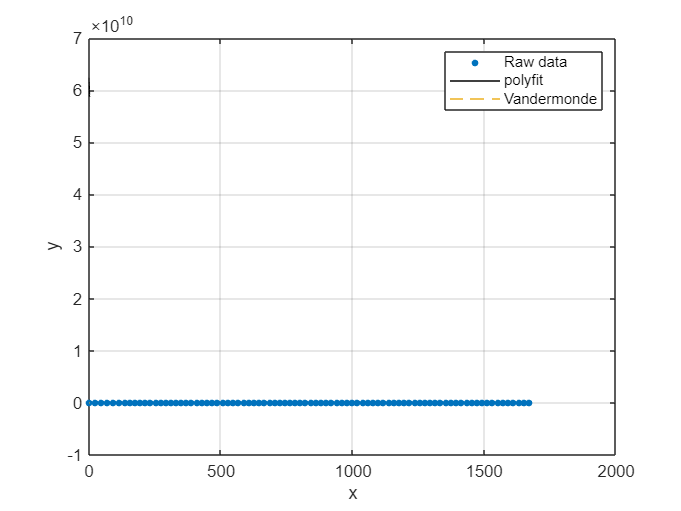

plot(xVis, yVisVI, '--')
legend('Raw data', 'polyfit', 'Vandermonde')

## Plot data

First, plot the raw data

figure;
plot(x, y, '.', 'MarkerSize', 12);
hold on;
grid on;
xlabel('x');
ylabel('y');

Plot approximation results using MATLABs functions

plot(xVis, yVisA, 'k');

Plot approximation results using the Vandermonde matrix

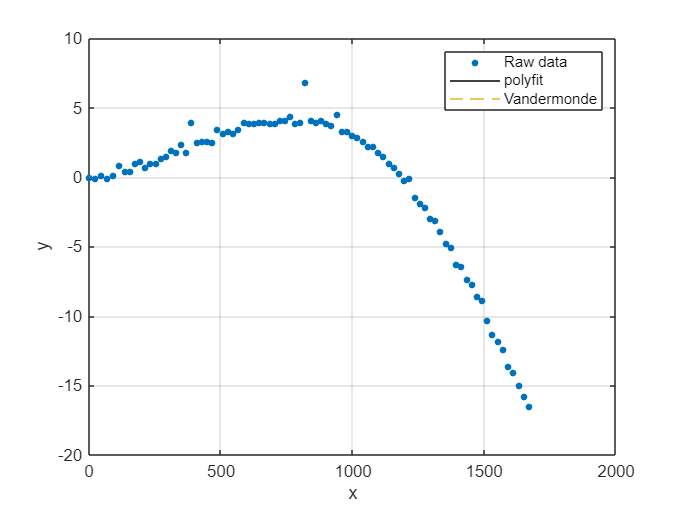

plot(xVis, yVisVA, '--')
legend('Raw data', 'polyfit', 'Vandermonde')